format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)
% latex(expres)

### **FBD og KD digram**

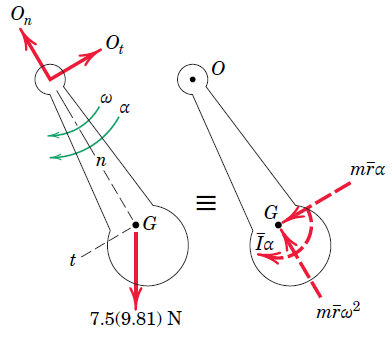

**INDSÆT I SI ENHEDER**

**GOD EQUATION**


$$F=m\cdot a$$


Divider med m for acceleration funktion

integrer for hastiheds funktion

integrer for sted funktion

### Kinetisk Energi

Translatorisk 

$T_{tran} = \frac{1}{2} \cdot m \cdot v^2$  [J]

Rotationel(stive legmer)

$T_{rot} = \frac{1}{2} \cdot I_O \cdot \omega^2$  [J]


$$\omega = \frac{2 \cdot \pi}{60} \cdot n$$



$$\alpha = \frac{a}{r} $$



$$\alpha = \frac{M_C}{I_C}$$


$M_C = I_C \cdot \alpha$    [J]


$$M_C = F \cdot l$$


### Gravational

$V_g = m \cdot g \cdot h$  [J]

### Energibevarelse

### **Inerti**

Om tyngdepunktet -- udregn eller opslag

I_G = k_G^2 * m

Flytning af inertimoment

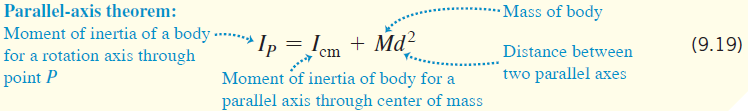

I_P = I_G + m * d^2

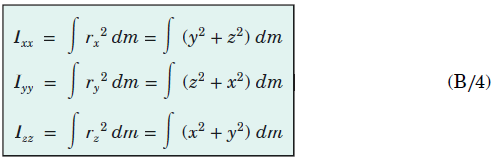

se også tabel D.4 i dynamic bogen

eksempel

clear all
L = 1.5; %m
m_bar = 2; % kg/m
g = 9.81; %m/s^2
M_tot = 3*L * m_bar

fra x-aksen

M = m_bar * L
M_tot = 3 * M
Sy_AB = 0 * M
Sy_BC = -L/2 * M
Sy_CD = -L * M

y_G = (Sy_AB + Sy_BC + Sy_CD) / M_tot

fra y-aksen

Sx_AB = -L/2 * M
Sx_BC = -L * M
Sx_CD = -L/2 * M

x_G = (Sx_AB + Sx_BC + Sx_CD) / M_tot

forskydelse af tyngdepunkter og endelig enerti

d_BC = L; %forskydelsen af BC's tyngde punkt 

d_CD = L; %forskydelsen af CD's tyngde punkt

stangAB_I_zz = 1/3 * M * L^2 %ligger op af rotations aksen

stangBC_I_zz = 1/3 * M * L^2 + M*d_BC^2 % forskydes til rotations aksen

stangCD_I_zz = 1/3 * M * L^2 + M*d_CD^2 % forskydes til rotations aksen

disp('-----------------------------------------')

%total inertimomentet er således
I_tot_zz = stangAB_I_zz + stangBC_I_zz + stangCD_I_zz

### Power


$$P=F\cdot v$$


For stive legmer

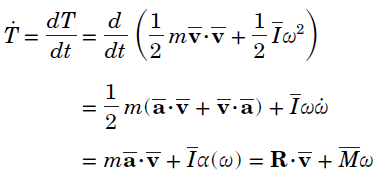

### Sted funktion


$$s(t) = s_0 + v_0 \cdot t + a_0 \cdot \frac{t^2}{2}$$


### Hastigheds funktion


$$v(t) = v_0 + a_0 \cdot t$$
 

### Komposanter et rectangulært koordinatsystem


$$v_{y0} = \sin(\theta) \cdot v_0$$



$$v_{x0} = \cos(\theta) \cdot v_0$$



$$v_{y0} = \tan(\theta) \cdot v_{x0}$$


**Rotation om fast punkt (tangielt koordinat system)**

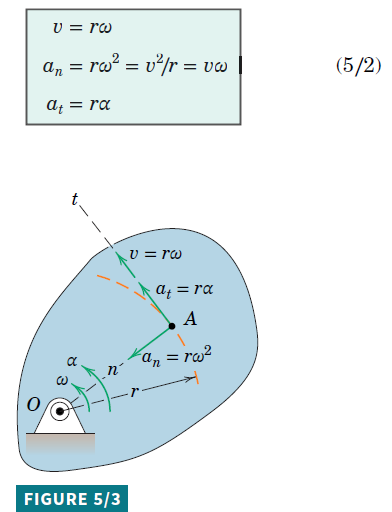

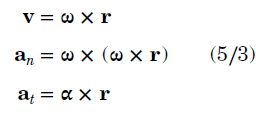

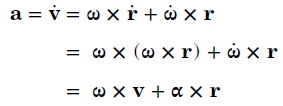

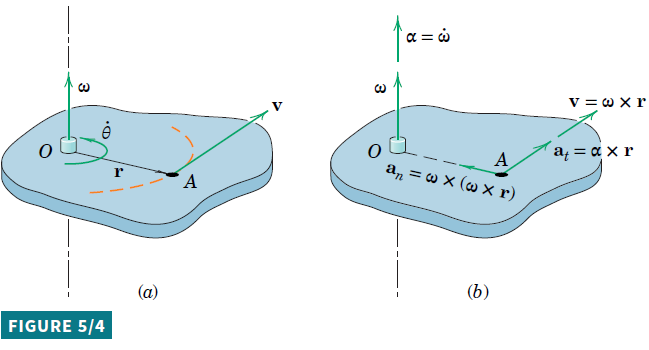

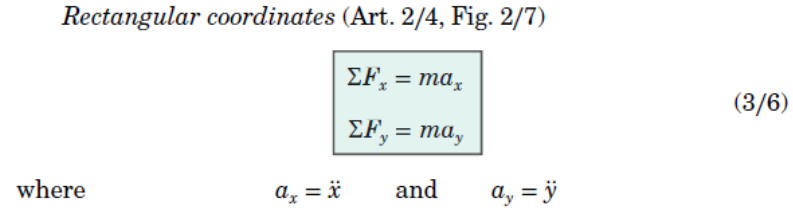

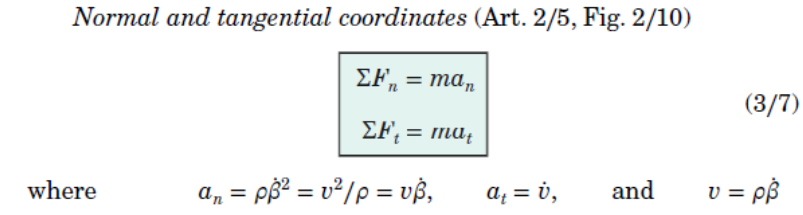

(for solide emner rotation)


$$a_t = r \cdot \alpha$$



$$a_n = r \cdot \omega^2$$


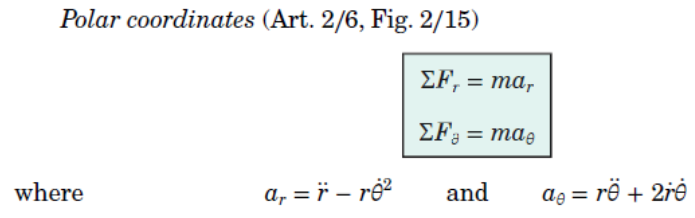

$\theta$ = vinklen

$\dot \theta = \omega =$ vinkelhastighed

$\ddot \theta = \alpha =$ vinkelaccelration

## Momentom

lineært

$F = m \cdot a$ integreres til


$$G = m\cdot v$$


Linær impuls er G (findes ved at gange med t)

Lineær moment er $\int^{t_2}_{t_1}\sum F dt$ (næsten ens) men altså impuls er forskellen i momentom se også side 88 i dynamikbogen 9th ed.

rotation

**Exempel herunder**

clear

syms t
g = -9.81 % m/s^2

g =         -9.81


a_0 = g % der omnavngives

a_0 =         -9.81


v_0 = 180 % m/s

v_0 =    180



theta = 60 % grader

theta =     60


alpha = 20 % grader

alpha =     20



disp("For y komposanten har vi strækningen for max højden")

For y komposanten har vi strækningen for max højden


disp("når hastigheden v er 0.")

når hastigheden v er 0.


disp("Vi finder tiden t til denne position")

Vi finder tiden t til denne position



v_y0 = sind(theta) * v_0 % y komposanten af hastigheden

v_y0 =        155.88



v_y_eq = v_y0 + a_0 * t % hastighedsligningen opstilles

$$v\_y\_eq = 90\,\sqrt{3}-\frac{981\,t}{100}$$


t_cal = solve(0 == v_y_eq, t); %tiden findes.
t_ = vpa(t_cal, 4) 

$$t\_ = 15.89$$


disp("Vi indsætter nu tiden i sted funktionen")

Vi indsætter nu tiden i sted funktionen


disp("ved at integrere hastighedsfunktionen")

ved at integrere hastighedsfunktionen



y(t) = int(v_y_eq, t) % integrere hastihedsfunktione

$$y(t) = -\frac{9\,t\,\left(109\,t-2000\,\sqrt{3}\right)}{200}$$


fprintf("Max højden vi når er %f m", vpa(y(t_cal),4))

Max højden vi når er 1238.532110 m

**1,24 km er således den maximale højde vi kommer op på.**

syms x

v_x0 = cosd(theta) * v_0 % y komposanten af hastigheden

v_x0 =     90




disp("Sted funktionen afhænger her kun af start hastigheden")

Sted funktionen afhænger her kun af start hastigheden


% displayFormula("x = v_x0 * t")
x_fun(t) = v_x0 * t

$$x\_fun(t) = 90\,t$$


x_fun_rampe(t) = v_x0 * t - v_x0 * t * cosd(alpha);

$$x\_fun\_vinkel(t) = \frac{6111006537516165\,t}{1125899906842624}$$


disp("Her kan t isolere og erstatte det i y-funktionen med x/v_x0")

Her kan t isolere og erstatte det i y-funktionen med x/v_x0




% y(x) = v_y0 * t + a_0 * t^2 / 2
y(x) = v_y0 * x/v_x0 + a_0 * (x/v_x0)^2 / 2

$$y(x) = \sqrt{3}\,x-\frac{109\,x^{2}}{180000}$$

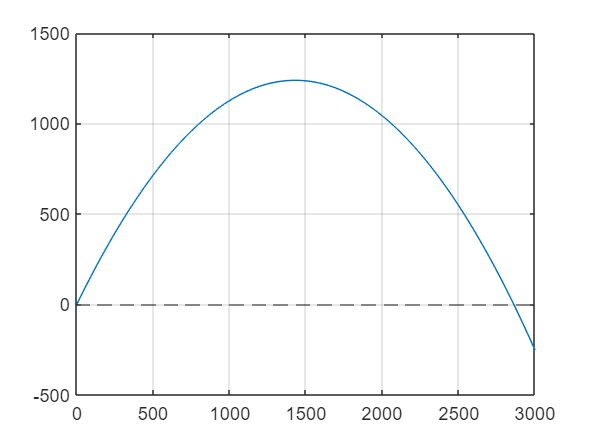


X_lin = linspace(0,3000,1000); 

plot(X_lin, y(X_lin)), yline(0, '--'), grid()

hold on

